%Mock Data Challenge
%Luis Mario Bres Castro
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/Func&data'
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/Lab11'
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/SDMBIGDAT19-master/CODES'
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/FinalLab4'

%Parameters
a1=[40, 100];

a2=[1, 50];


a3=[1, 15];


tn = 3;
%Vectors covering a1, a2, and a3 parameters
v1 = [randi(a1), randi(a2), randi(a3)];

v1 =     67    25     4


v2 = [63,27,10];

v2 =     63    27    10


v3 = [76,51,4];

v3 =     76    51     4



%TrainingData.mat and AnalysisData.mat
trainingData=load('TrainingData.mat');
tData=trainingData.trainData; %Training Data vector
sampFreq=trainingData.sampFreq; %Sampling Frequency
dataVec=load('AnalysisData.mat');
dataVec=dataVec.dataVec; %Analysis Data Vector

%Time vector
nSamples=length(dataVec);
dataLen=nSamples/sampFreq;
timeVec=(0:(nSamples-1))/sampFreq;

timeVec =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479




%Estimate PSD

[pxx,posFreq]=pwelch(tData,1024,[],[],sampFreq);

pxx = 	1.0e+-42 *

    0.0246
    0.0578
    0.0617
    0.0534
    0.0439
    0.0447
    0.0565
    0.0585
    0.0560
    0.0654


posFreq =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



PSD = interp1(1:length(pxx),pxx,linspace(1,length(pxx),1025),'cubic');
posFreq = interp1(1:length(posFreq),posFreq,linspace(1,length(posFreq),1025),'linear');


%From SNRcalcMod1&2, to obtain LLR values for multiple noise realizations
M=1000;
H01=zeros(1,M);
H02=zeros(1,M);
H03=zeros(1,M);
sqrtPSD = sqrt(PSD);
b = fir2(100,posFreq/posFreq(end),sqrtPSD);

for i= 1:M 
    inNoise = randn(1,nSamples); 
    noiseVec = sqrt(sampFreq)*fftfilt(b,inNoise);
    H01(i) = glrtqcsig(noiseVec,PSD,v1,nSamples);
end

    1.3268

    2.8553

    0.3358

    0.0249

    2.1589

    0.0042

    1.3123

    1.7708

    1.0747

    1.0273

    0.5049

    1.4868

    0.8396

    2.3744

    1.0252

    0.1951

    0.0023

    0.0929

    0.0050

    4.7118

    0.0727

    0.0927

    0.9967

    0.0043

    0.0089

    0.0708

   6.2829e-04

    3.0978

    0.0015

    3.1111

    0.8353

    0.7939

    0.0048

   5.2244e-04

    0.1557

    2.1554

    0.0160

    0.0326

    1.7754

    0.2654

    0.3805

    0.0050

    0.0074

    0.7945

    0.1632

    0.1653

    2.2344

    4.8753

    1.4105

   3.0236e-06

    2.9886

    0.3966

    0.5223

    0.1948

    4.3875

    1.4574

    1.5994

    0.1984

    0.0183

    0.1865

    0.7588

    0.3639

    4.7431

    1.9058

    0.0443

    0.9193

    0.0737

    2.6191

    2.6941

    0.0383

    4.6444

    2.2369

    1.3037

    0.0510

    1.1459

    0.6770

    0.4349

    0.8433

    0.2945

    0.0261

    0.3406

    0.0237

    0.0


for i= 1:M 
    inNoise = randn(1,nSamples); 
    noiseVec = sqrt(sampFreq)*fftfilt(b,inNoise);
    H02(i) = glrtqcsig(noiseVec,PSD,v2,nSamples);
end

    0.0367

    0.0013

    0.4711

    1.1184

    1.6632

    0.1304

    0.0708

    0.2060

    0.0957

    0.9643

    0.9579

    0.6840

    0.6016

    0.0055

    0.4464

    0.9866

    0.6176

    0.0332

    5.8637

    1.7011

    0.2150

    0.2150

    0.7855

    0.1762

    2.1209

    0.1622

    0.0079

    0.0091

    0.3474

    1.8327

    0.8669

   3.4254e-04

    1.6938

    0.0554

    0.0157

    2.3587

    0.0126

    0.0148

    3.9013

    0.0494

    0.2226

    0.0610

    2.0705

    0.7903

    0.0314

    0.1697

    0.2835

    0.4991

    2.2928

    5.2548

    0.5322

    2.6240

    1.2138

    0.1601

    0.0910

    0.0742

    0.0465

    1.5503

    2.3070

    1.0191

   6.5650e-04

    0.5589

    1.9572

    0.7091

    0.0270

    0.1744

    0.1988

    0.5088

    1.4504

    0.3572

    2.3247

    0.2327

    0.1247

    0.0317

    3.1878

    0.4367

    2.4001

    7.1273

    1.4220

    0.2896

    3.5752

    0.1393

    2.8810


for i= 1:M 
    inNoise = randn(1,nSamples); 
    noiseVec = sqrt(sampFreq)*fftfilt(b,inNoise);
    H03(i) = glrtqcsig(noiseVec,PSD,v3,nSamples);
end

    0.3452

    0.2540

    2.0347

    0.0769

    1.3851

    0.0035

    1.3763

    1.3447

    0.1269

    2.5383

    0.6548

    0.1238

    0.0275

    3.3264

    0.0599

    0.0278

    0.0422

    0.0118

    1.9725

    0.0066

    0.6767

    0.5391

   5.9483e-05

    0.2000

    0.0087

    0.7269

    0.0638

    0.0802

    0.1274

    0.0777

    0.6349

    1.0523

    0.2827

    0.0391

    0.3466

    1.7433

    0.0685

    0.3932

    0.4045

    3.1589

    1.3069

    0.2488

    0.0603

    1.6397

    0.6662

    0.0130

    0.3447

    1.2581

    1.4373

    0.1060

    0.0045

    0.5186

    0.1799

    0.1098

    3.7675

    0.2090

    1.6280

    0.0098

    0.0035

    0.1135

    1.7121

    0.3478

    0.5721

    0.9081

    0.8998

    0.1846

    0.6415

    0.0721

    0.2238

    3.2111

    0.6385

    0.3668

    0.5159

    0.1042

    0.3781

    1.0248

    0.2250

    1.9758

    5.7657

    0.8741

    1.2175

    0.2223

    0.1111

 

% GLRT for data files
Gamma1 = glrtqcsig(dataVec,PSD,v1,nSamples);

    0.0543



Gamma2 = glrtqcsig(dataVec,PSD,v2,nSamples);

   59.6568



Gamma3 = glrtqcsig(dataVec,PSD,v3,nSamples);

    0.5334




%Significance Results
alpha1 = sum(H01>=Gamma1)/M  %For Trial 1

alpha1 = 0.8050

alpha2 = sum(H02>=Gamma2)/M  %For Trial 2

alpha2 = 0

alpha3 = sum(H03>=Gamma3)/M  %For Trial 3

alpha3 = 0.4650



%There is a detected signal, using parameters from PSO
%it was found that it was a significance of ~0 for trial 2.

%Calling PSO

% parameter structrue for glrtqc4pso
nite=2000;
nruns=8;
snr=1;
In = struct('timeVec',timeVec,...
                'time2',timeVec.^2,...
                'time3',timeVec.^3,...
                'dataY',dataVec,...
                'samplFreq',sampFreq,...
                'psdVec',PSD,...
                'snr',snr,...
                'rmin',[a1(1),a2(1),a3(1)],...
                'rmax',[a1(2),a2(2),a3(2)]);

psoParams = struct('steps',nite);
outStruct = glrtqcpso(In,psoParams,nruns);

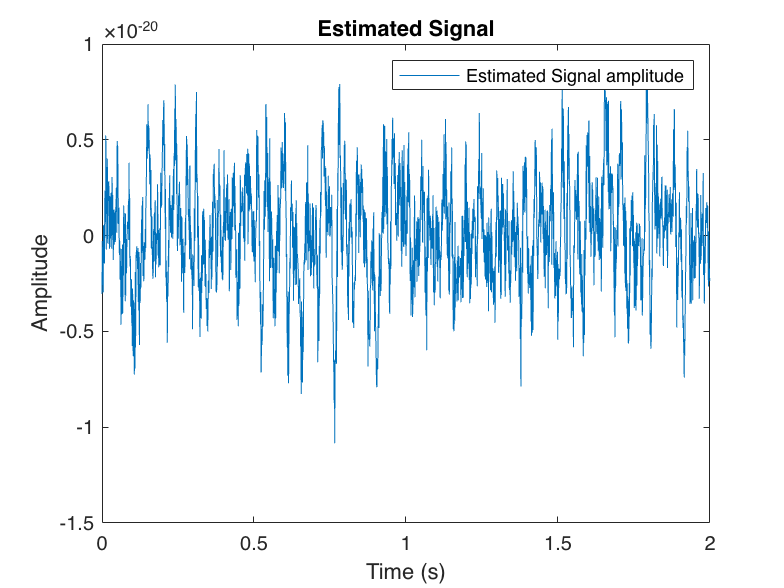

% generate colored noise
filtOrdr = 100;

fl = floor(nSamples/10+1); 
noiseVec1 = statgaussnoisegen(nSamples+fl,[posFreq(:),PSD(:)],filtOrdr,sampFreq);
noiseVec1 = noiseVec1(fl+1:end);

% generate qc and normalize to snr
sigVec1 = crcbgenqcsig(timeVec,1,v2);
% norm of the signal squared is inner product of signal with itself
normSigSqrd = innerprodpsd(sigVec1,sigVec1,sampFreq,PSD);
sigVec1 = snr*sigVec1/sqrt(normSigSqrd);

EstVec = noiseVec1 + sigVec1;
figure 
plot(timeVec,EstVec)
legend('Estimated Signal amplitude');
title('Estimated Signal');
ylabel('Amplitude');
xlabel('Time (s)');

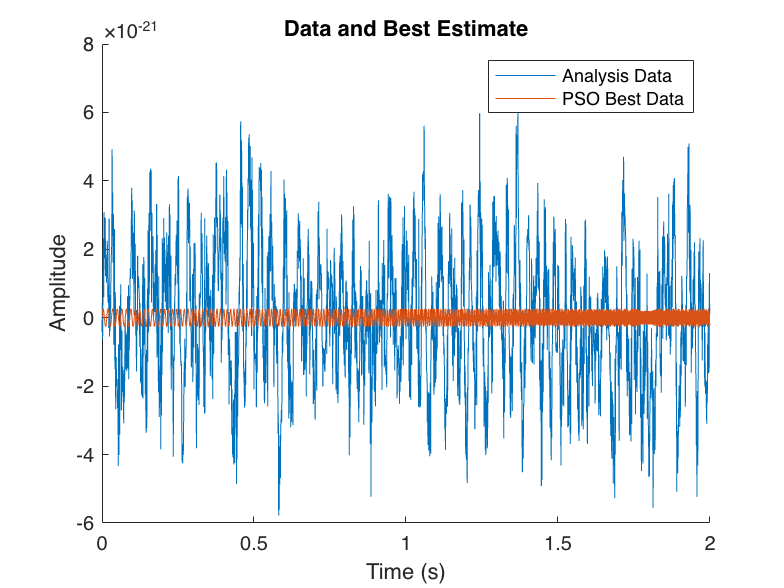

figure
hold on
plot(timeVec,dataVec);
plot(timeVec,outStruct.bestSig)
hold off
legend('Analysis Data','PSO Best Data');
title('Data and Best Estimate');
ylabel('Amplitude');
xlabel('Time (s)');

disp(['Estimated parameters: a1=',num2str(outStruct.bestQcCoefs(1)),...
                          '; a2=',num2str(outStruct.bestQcCoefs(2)),...
                          '; a3=',num2str(outStruct.bestQcCoefs(3))]);

Estimated parameters: a1=63.0819; a2=26.8865; a3=10.0325


% figure
% for lpruns = 1:nruns
%     plot(timeVec,outStruct.allRunsOutput(lpruns).estSig);
% end
% hold off
% legend(['Estimated Signals from ',num2str(nruns),' runs']);
% title('Data, Signal, and Best Estimates');
% ylabel('Amplitude');
% xlabel('Time (s)');